emails = readtable("emails.csv", ReadRowNames=true, ReadVariableNames=true, VariableNamingRule="preserve");

Draw ROC curve for 5NN

train_data = emails(1001:end, :);
test_data = emails(1:1000, :);
mdl = fitcknn(train_data, 'Prediction', Distance='euclidean', NumNeighbors=5);
[label, sc] = predict(mdl, test_data(:,1:end-1));

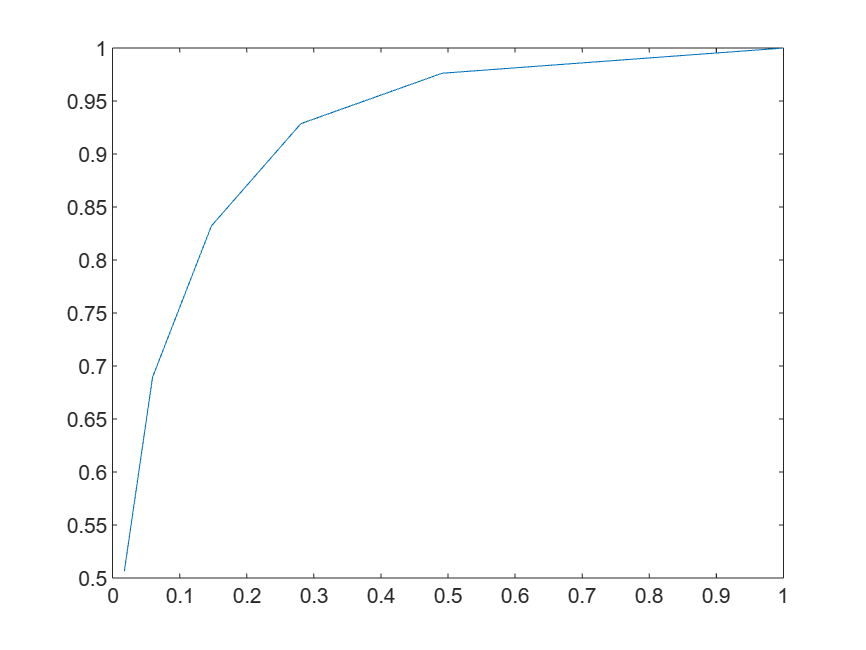

[cfd, IND] = sort(sc(:,2));
y = table2array(test_data(:,end));
y = y(IND);
coord1 = draw_roc(y, cfd);
plot(coord1(:,1), coord1(:,2))

Draw ROC curve for logistic regression

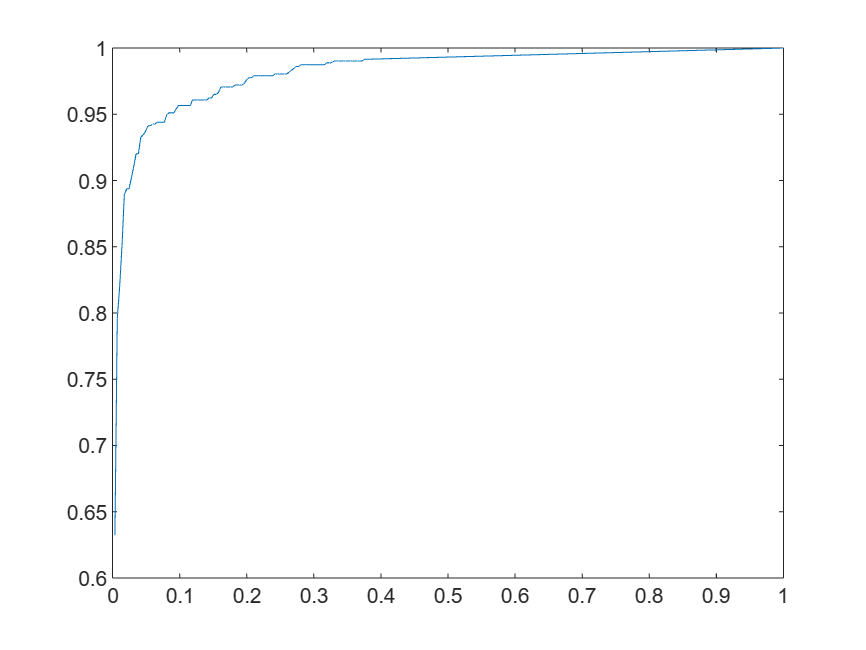

train_data_X = table2array(train_data(:,1:end-1));
train_data_y = table2array(train_data(:,end));
test_data_X = table2array(test_data(:,1:end-1));
test_data_y = table2array(test_data(:,end));

theta = logistic_fit(train_data_X, train_data_y, 0.05);

cfd2 = logistic(theta, test_data_X);
[cfd2, IND2] = sort(cfd2);

coord2 = draw_roc(test_data_y(IND2), cfd2);
plot(coord2(:,1), coord2(:,2))

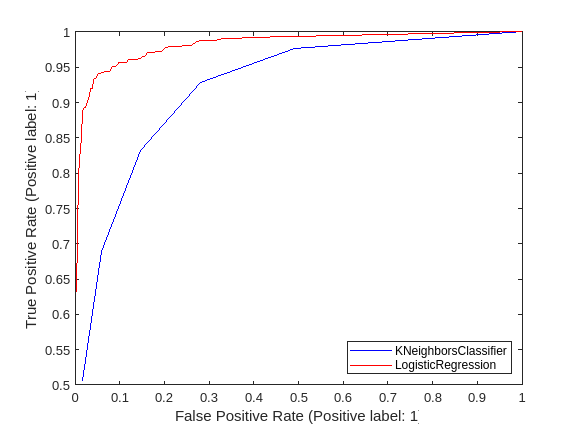

plot(coord1(:,1), coord1(:,2), 'b');
hold on
plot(coord2(:,1), coord2(:,2), 'r');
hold off
xlabel("False Positive Rate (Positive label: 1)")
ylabel("True Positive Rate (Positive label: 1)")
legend("KNeighborsClassifier", "LogisticRegression", Location="southeast")
exportgraphics(gcf, "hw3_5.pdf", ContentType="vector")

function res = draw_roc(y, c)
    res = [];
    num_neg = sum(y == 0);
    num_pos = sum(y == 1);
    TP = 0;
    FP = 0;
    last_TP = 0;
    for k = 1:length(y)
        if (k > 1) && (c(k) ~= c(k-1)) && (TP > last_TP)
            FPR = FP/num_neg;
            TPR = TP/num_pos;
            res = [res; TPR FPR];
            last_TP = TP;
        end
        if y(k) == 1
            TP = TP + 1;
        else
            FP = FP + 1;
        end
    end
    FPR = FP/num_neg;
    TPR = TP/num_pos;
    res = [res; TPR FPR];

%     plot(res(:, 2), res(:,1))
end

function theta = logistic_fit(X, y, eta)
    theta = zeros(1,size(X,2));
    for k = 1:3000
        d = (logistic(theta, X) - y)' * X ./ length(y);
        theta = theta - eta .* d;
    end
end

function ret = logistic(theta, x)
    ret = 1 ./ (exp(-theta*x')' + 1);
end